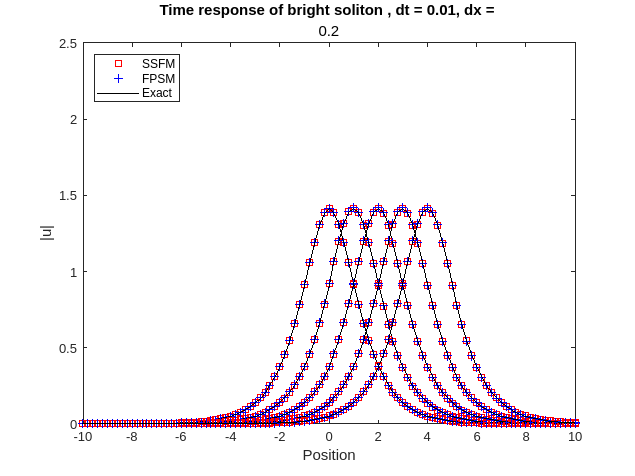

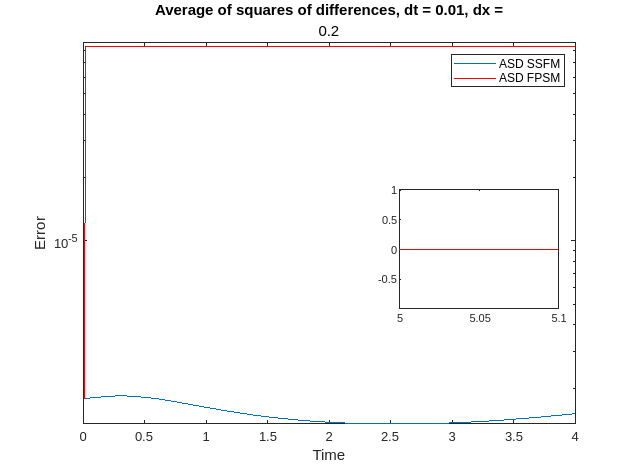

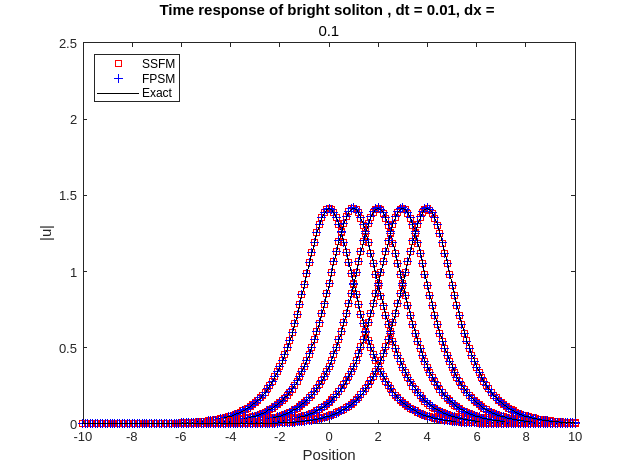

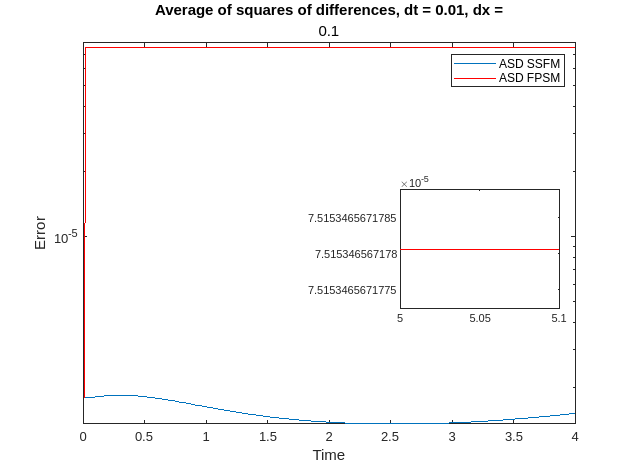

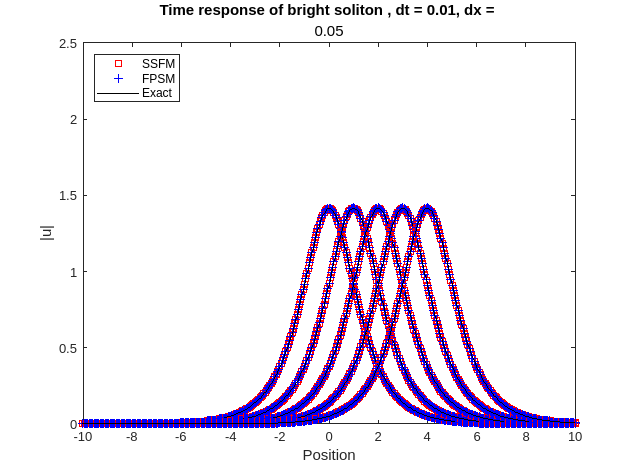

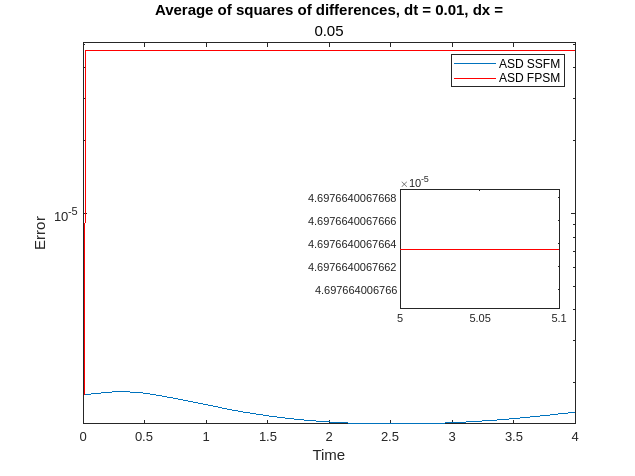

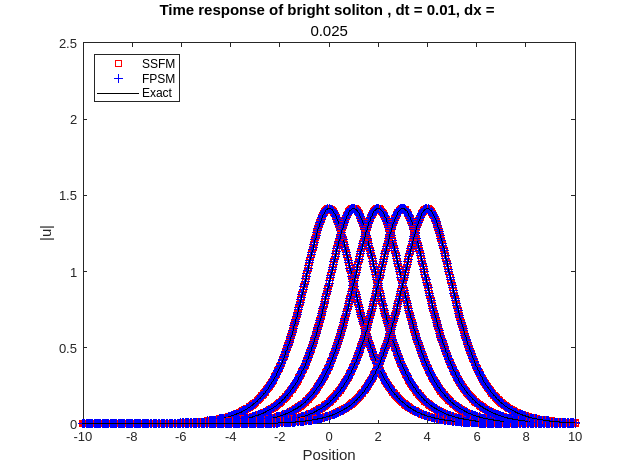

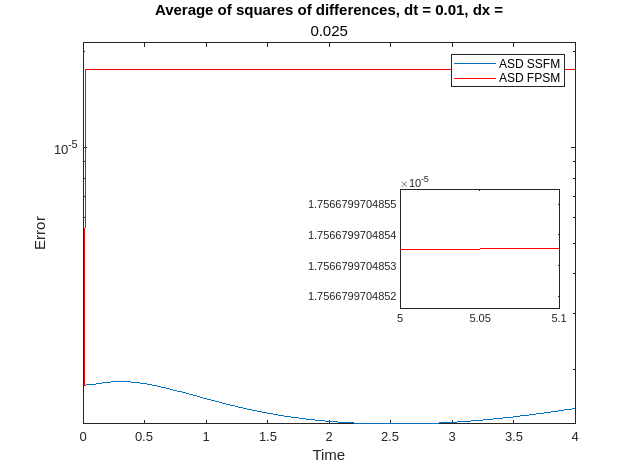

clear
clc
tf = 4;
dt = 0.01;

vdx = [0.2 0.1 0.05 0.025];
clf
LINF = zeros(length(vdx),2);

for w=1:length(vdx)
    dx = vdx(w);
    L = 200; % Intervalo de espacio
    N = L/dx; % Numero de intervalos en x
    
    n = (-N/2: 1 : N/2 - 1)';
    x = n * dx; % Espacio
    k = 2 * n * pi / L; % Wavenumbers
    
    
    M = tf/dt; 
    m = (1 : 1 : M)';
    t = m * dt;
    
    x0=0; % Posicion inicial
    psi=1;
    eta=1; % Amplitud
    v=1; % Velocidad
    
    u1 = zeros(length(x),length(t)); % Split-step resultados
    u2 = zeros(length(x),length(t)); % Fourier pseudospectral resultados
    ut = zeros(length(x),length(t));
    
    f=@(x,t) (2*eta)^(0.5)*exp(1i*(0.5*v*x+(eta-0.25*v^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v*t-x0));
    
    
    u1(:,1)=f(x,0);             u2(:,1)=f(x,0);         
    u1(:,end)=f(x,t(end));      u2(:,end)=f(x,t(end)); 
    u1(1,:)=f(-L,t);            u2(1,:)=f(-L,t);       
    u1(end,:)=f(L,t);           u2(end,:)=f(L,t);      
    
    q=u1(:,1);
    
    ut(:,1) = f(x,t(1));
    for m = 2:length(t)
        %SSFM
        q = ifft(fftshift(fftshift(fft(exp(dt * 1i * (abs(q).*abs(q))) .* q)).*exp(-dt * 1i * k.*k)));
        u1(2:end-1,m) = q(2:end-1);
    
        %FPSM
        qn = f(x,t(m-1)) + 2*1i*ifft(sin(k.^2*(pi^2/L^2)*dt).*fft(f(x,t(m))))-4*1i*dt*(abs(f(x,t(m))) .* abs(f(x,t(m)))) .* f(x,t(m));
        u2(2:end-1,m) = qn(2:end-1);
    
        ut(:,m) = f(x,t(m));
    end
    figure;
    plot(x, abs(u1(:,1)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,1)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,1)),'k-',LineWidth=1);

    plot(x, abs(u1(:,end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end/4)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end/4)),'k-',LineWidth=1);
    
    plot(x, abs(u1(:,end/2)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end/2)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end/2)),'k-',LineWidth=1);

    plot(x, abs(u1(:,3*end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,3*end/4)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,3*end/4)),'k-',LineWidth=1);

    plot(x, abs(u1(:,end)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end)),'k-',LineWidth=1);

    ylim([0,eta*(5/2)])
    xlim([-10,10])
    xlabel('Position');
    ylabel('|u|') 

    title('Time response of bright soliton , dt = 0.01, dx = ' , num2str(dx));
    legend('SSFM','FPSM','Exact','Location', 'northwest')
    hold off
    
    figure;
    error1=mean(abs((ut-u1).^2),1)'; error2=mean(abs((ut-u2).^2),1)';
    semilogy(t,error1)
    hold on
    semilogy(t,error2,'r')
    legend('ASD SSFM', 'ASD FPSM')
    xlabel('Time')
    ylabel('Error')
    ylim([0,max(error2)+2*max(error1)])
    title('Average of squares of differences, dt = 0.01, dx =' , num2str(dx));
    axes('position',[.63 .35 .25 .25])
    box on 
    plot([5 5.1],error2(end/2-1:end/2),'r')
    axis tight
    hold off
    Linf1=max(max(abs(ut-u1).^2));
    Linf2=max(max(abs(ut-u2).^2));
    LINF(w,:) = [Linf1, Linf2];
end

LINF

LINF =     0.0002    0.0149
    0.0002    0.0137
    0.0002    0.0094
    0.0002    0.0013



order = zeros(3, 2);
for i=2:4
    order(i,2) = log(LINF(i,2)/LINF(i-1,2))/log(vdx(1,i)/vdx(1,i-1));
    order(i,1) = log(LINF(i,1)/LINF(i-1,1))/log(vdx(1,i)/vdx(1,i-1));

end
table(transpose(vdx),LINF, order)

order =          0         0
   -0.0065    0.1200
   -0.0000    0.5482
   -0.0005    2.8438


ans = 4x3 table
    Var1               LINF                        order           
    _____    ________________________    __________________________

      0.2    0.00018535      0.014933              0              0
      0.1    0.00018619      0.013742     -0.0065008        0.11998
     0.05    0.00018619     0.0093972    -4.0684e-14        0.54825
    0.025    0.00018626      0.001309    -0.00053167         2.8438


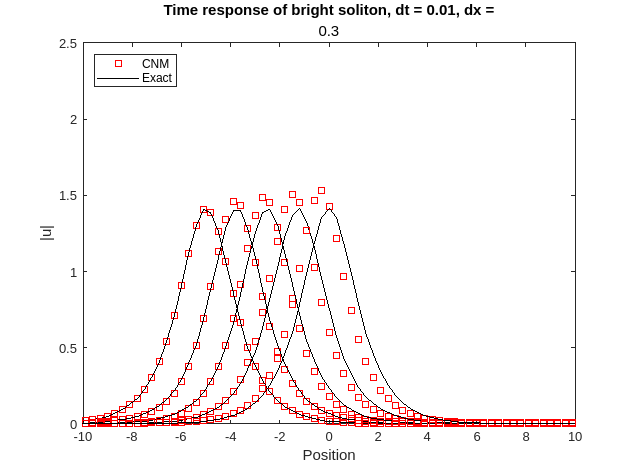

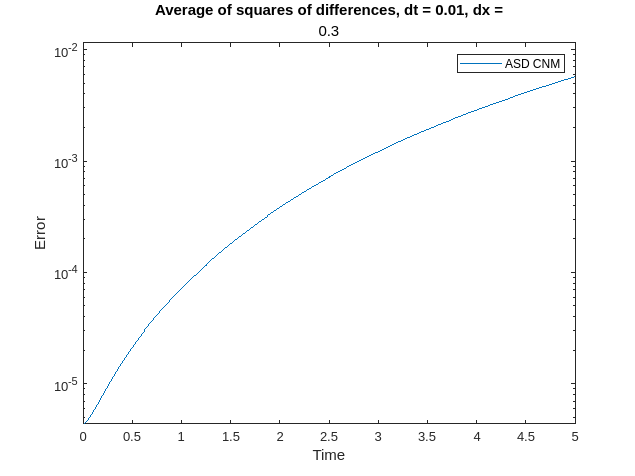

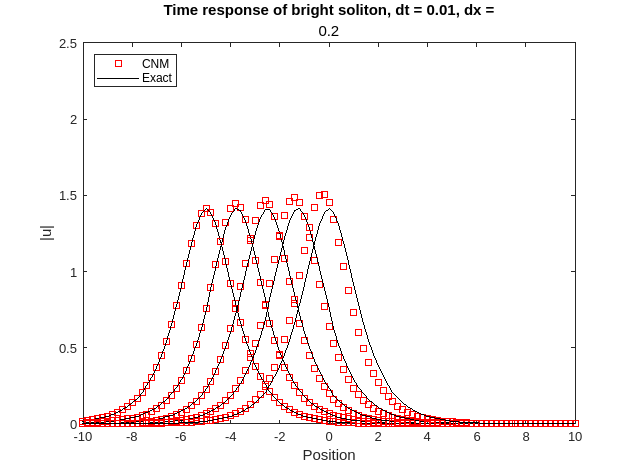

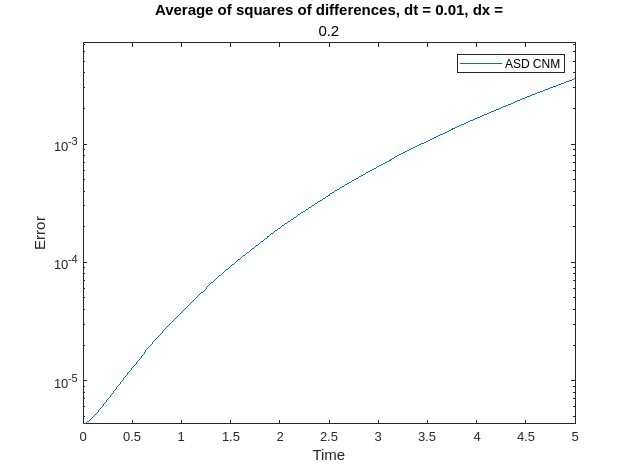

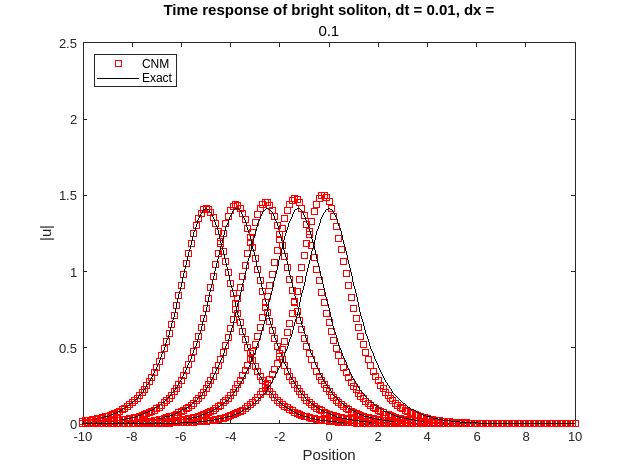

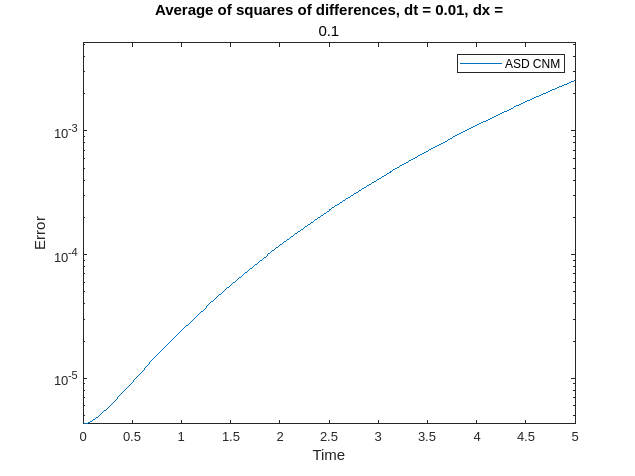

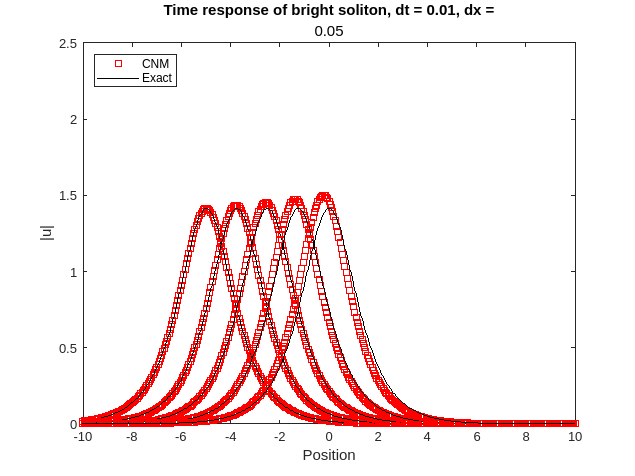

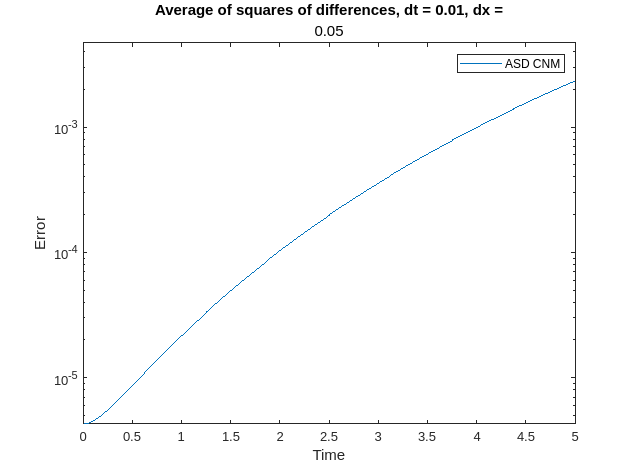

clear
clc
tf = 5;
dt = 0.01;
vdx = [0.3 0.2 0.1 0.05];
clf
LINF = zeros(length(vdx),1);
for w=1:length(vdx)
    dx = vdx(w);
    L = 100;
    N = floor(L/dx); 
    n = (-N-1 : 1 : N)';
    x = n * dx;

    M = floor(tf/dt);
    
    m = (1 : 1 : M)';
    t = m * dt;
    
    x0=-5;
    psi=0;
    xi=1;
    eta=1;
    c=1;
    
    
    lambda=1/(2*(dx^2));
    
    u = zeros(2*N+2,M);
    ut = zeros(2*N+2, M);
    
    q = @(x,t) (2*eta)^(0.5)*exp(1i*(0.5*c*x+(eta-0.25*c^2)*t+psi)).*sech(eta^(0.5)*(x-c*t-x0));
    
    u(:,1) = q(x,t(1));
    ut(:,1) = q(x,t(1));
    
    
    A = zeros(2*N+2,2*N+2);
    B = zeros(2*N+2,2*N+2);
    
    
    for i=1:2*N+2
        A(i,i) = (1i/dt - 1/(dx^2));
        B(i,i) = (1i/dt + 1/(dx^2));
        if i>1
            A(i-1,i)= lambda; A(i,i-1)=  lambda;
            B(i-1,i)= -lambda; B(i,i-1)=  -lambda;
        end
    end
    F = -(abs(u(:,1)).^2).*u(:,1)+B*u(:,1)-(abs(u(:,1)).^2).*u(:,1);
    u(:,2) = A\F;
    ut(:,2) = q(x,t(2));
    
    
    for j=2:M-1
        F = -(abs(u(:,j+1)).^2).*u(:,j+1)+B*u(:,j)-(abs(u(:,j)).^2).*u(:,j);
        u(:,j+1)= A\F;
        ut(:,j+1) = q(x,t(j+1));
    end
    figure;
    plot(x, abs(u(:,1)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,1)),'k-',LineWidth=1);

    plot(x, abs(u(:,end/4)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,end/4)),'k-',LineWidth=1);
    
    plot(x, abs(u(:,end/2)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(ut(:,end/2)),'k-',LineWidth=1);

    plot(x, abs(u(:,3*end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(ut(:,3*end/4)),'k-',LineWidth=1);

    plot(x, abs(u(:,end)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,end)),'k-',LineWidth=1);

    ylim([0,eta*(5/2)])
    xlim([-10,10])
    xlabel('Position');
    ylabel('|u|') 
    
    title('Time response of bright soliton, dt = 0.01, dx =' ,num2str(dx));
    legend('CNM','Exact','Location', 'northwest')
    hold off
    figure;
    error1=mean(abs((ut-u).^2),1)';
    semilogy(t,error1)
    legend('ASD CNM')
    xlabel('Time')
    ylabel('Error')
    ylim([0,2*max(error1)])
    title('Average of squares of differences, dt = 0.01, dx =' , num2str(dx));
    hold off
    Linf1=max(mean(abs(ut-u).^2));
    LINF(w,1) = Linf1;
end


order = zeros(3, 2);
for i=2:4
    order(i,1) = log(LINF(i,1)/LINF(i-1,1))/log(vdx(1,i)/vdx(1,i-1));

end
table(transpose(vdx),LINF, order)

ans = 4x3 table
    Var1      LINF             order       
    ____    _________    __________________

     0.3    0.0057388          0          0
     0.2    0.0035726     1.1689          0
     0.1    0.0025668    0.47701          0
    0.05    0.0023467    0.12931          0


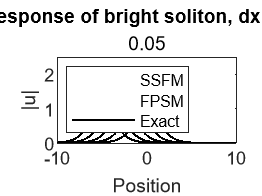

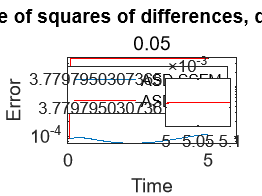

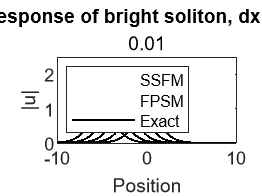

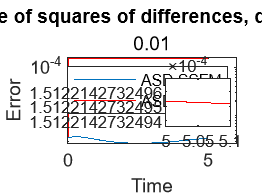

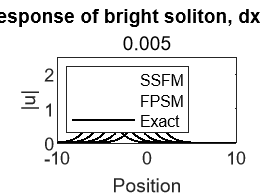

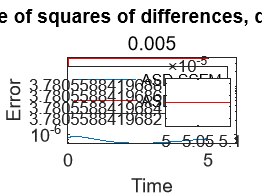

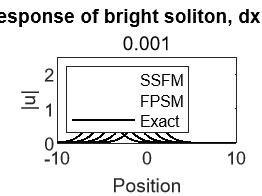

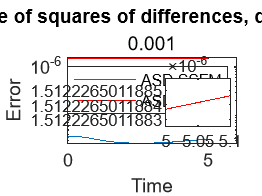

clear
clc
tf = 5;
dx = 0.2;
vdt = [0.05 0.01 0.005 0.001];
clf
LINF = zeros(length(vdt),2);

for w=1:length(vdt)
    L = 100; % Intervalo de espacio
    N = L/dx; % Numero de intervalos en x
    
    n = (-N/2: 1 : N/2 - 1)';
    x = n * dx; % Espacio
    k = 2 * n * pi / L; % Wavenumbers
    
    dt= vdt(w);
    M = tf/dt; 
    m = (1 : 1 : M)';
    t = m * dt;
    
    x0=-5; % Posicion inicial
    psi=1;
    eta=1; % Amplitud
    v=1; % Velocidad
    
    u1 = zeros(length(x),length(t)); % Split-step resultados
    u2 = zeros(length(x),length(t)); % Fourier pseudospectral resultados
    ut = zeros(length(x),length(t));
    
    f=@(x,t) (2*eta)^(0.5)*exp(1i*(0.5*v*x+(eta-0.25*v^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v*t-x0));
    
    
    u1(:,1)=f(x,0);             u2(:,1)=f(x,0);         
    u1(:,end)=f(x,t(end));      u2(:,end)=f(x,t(end)); 
    u1(1,:)=f(-L,t);            u2(1,:)=f(-L,t);       
    u1(end,:)=f(L,t);           u2(end,:)=f(L,t);      
    
    q=u1(:,1);
    
    ut(:,1) = f(x,t(1));
    for m = 2:length(t)
        %SSFM
        q = ifft(fftshift(fftshift(fft(exp(dt * 1i * (abs(q).*abs(q))) .* q)).*exp(-dt * 1i * k.*k)));
        u1(2:end-1,m) = q(2:end-1);
    
        %FPSM
        qn = f(x,t(m-1)) + 2*1i*ifft(sin(k.^2*(pi^2/L^2)*dt).*fft(f(x,t(m))))-4*1i*dt*(abs(f(x,t(m))) .* abs(f(x,t(m)))) .* f(x,t(m));
        u2(2:end-1,m) = qn(2:end-1);
    
        ut(:,m) = f(x,t(m));
    end
    figure;
    plot(x, abs(u1(:,1)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,1)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,1)),'k-',LineWidth=1);

    plot(x, abs(u1(:,end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end/4)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end/4)),'k-',LineWidth=1);
    
    plot(x, abs(u1(:,end/2)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end/2)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end/2)),'k-',LineWidth=1);

    plot(x, abs(u1(:,3*end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,3*end/4)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,3*end/4)),'k-',LineWidth=1);

    plot(x, abs(u1(:,end)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end)),'k-',LineWidth=1);

    ylim([0,eta*(5/2)])
    xlim([-10,10])
    xlabel('Position');
    ylabel('|u|') 

    title('Time response of bright soliton, dx = 0.2, dt =' , num2str(dt));
    legend('SSFM','FPSM','Exact','Location', 'northwest')
    hold off

    figure;
    error1=mean(abs((ut-u1).^2),1)'; error2=mean(abs((ut-u2).^2),1)';
    semilogy(t,error1)
    hold on
    semilogy(t,error2,'r')
    legend('ASD SSFM', 'ASD FPSM')
    xlabel('Time')
    ylabel('Error')
    ylim([0,max(error2)+2*max(error1)])
    title('Average of squares of differences, dx = 0.2, dt =' , num2str(dt));
    axes('position',[.63 .35 .25 .25])
    box on 
    plot([5 5.1],error2(end/2-1:end/2),'r')
    axis tight
    hold off
    Linf1=max(mean(abs(ut-u1).^2));
    Linf2=max(mean(abs(ut-u2).^2));
    LINF(w,:) = [Linf1, Linf2];
end

LINF

LINF =     0.0001    0.0038
    0.0000    0.0002
    0.0000    0.0000
    0.0000    0.0000


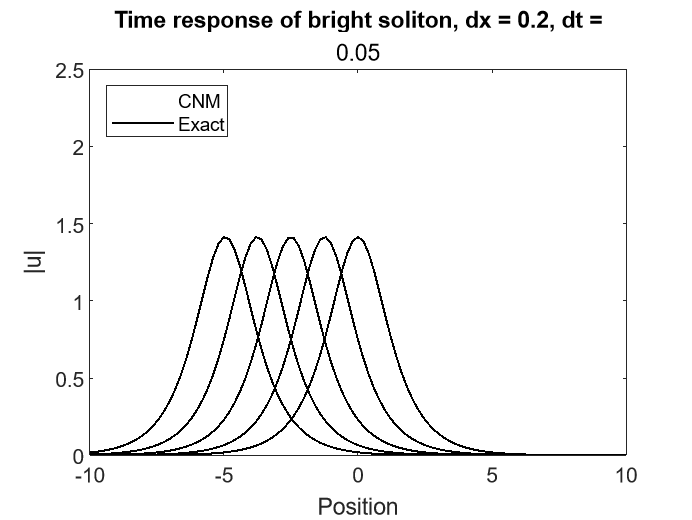

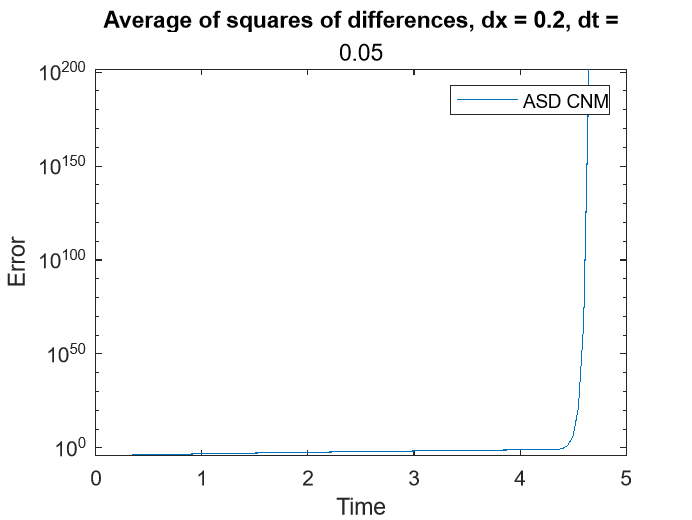

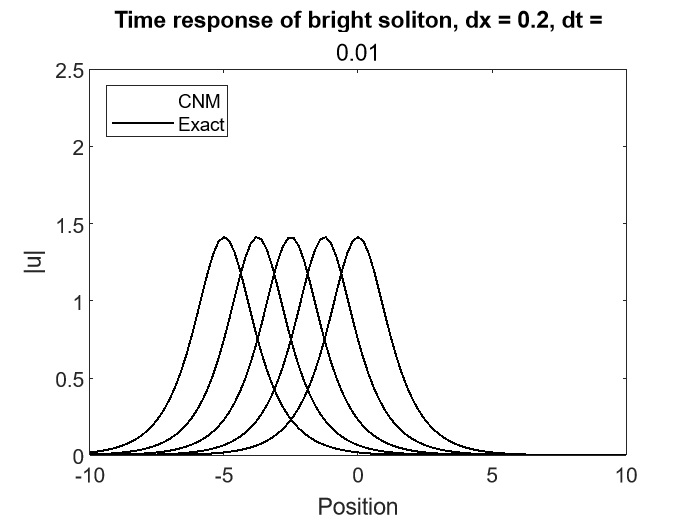

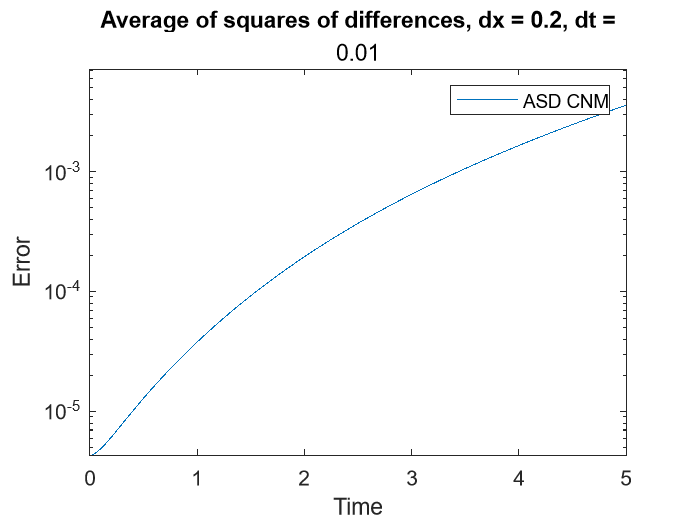

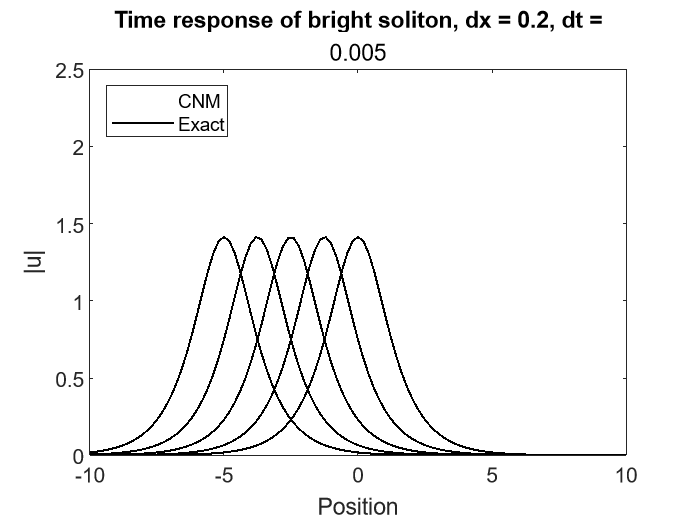

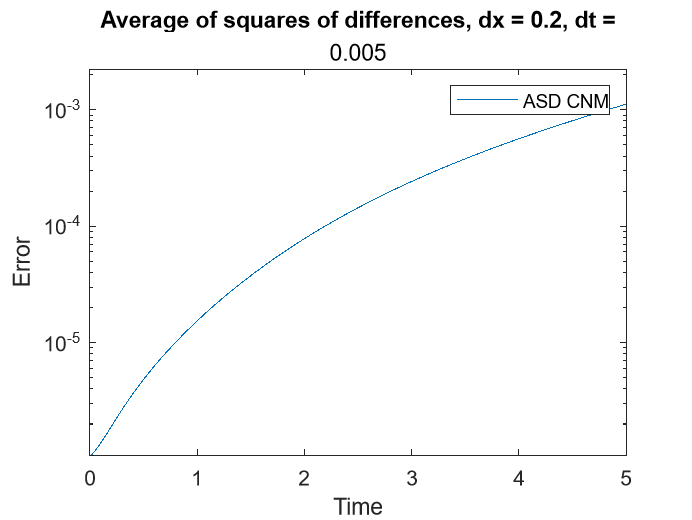

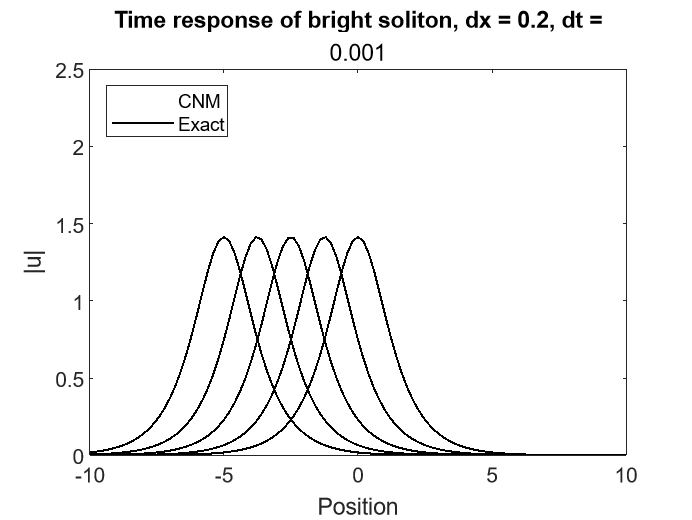

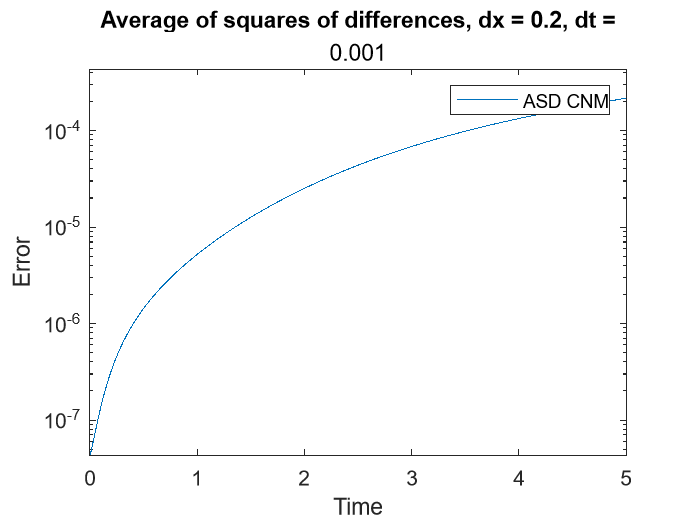

clear
clc
tf = 5;
dx = 0.2;
vdt = [0.05 0.01 0.005 0.001];
LINF = zeros(length(vdt),1);
clf
for w=1:length(vdt)
    L = 100;
    N = floor(L/dx); 
    n = (-N-1 : 1 : N)';
    x = n * dx;

    dt = vdt(w);
    M = floor(tf/dt);
    
    m = (1 : 1 : M)';
    t = m * dt;
    
    x0=-5;
    psi=0;
    xi=1;
    eta=1;
    c=1;
    
    
    lambda=1/(2*(dx^2));
    
    u = zeros(2*N+2,M);
    ut = zeros(2*N+2, M);
    
    q = @(x,t) (2*eta)^(0.5)*exp(1i*(0.5*c*x+(eta-0.25*c^2)*t+psi)).*sech(eta^(0.5)*(x-c*t-x0));
    
    u(:,1) = q(x,t(1));
    ut(:,1) = q(x,t(1));
    
    
    A = zeros(2*N+2,2*N+2);
    B = zeros(2*N+2,2*N+2);
    
    
    for i=1:2*N+2
        A(i,i) = (1i/dt - 1/(dx^2));
        B(i,i) = (1i/dt + 1/(dx^2));
        if i>1
            A(i-1,i)= lambda; A(i,i-1)=  lambda;
            B(i-1,i)= -lambda; B(i,i-1)=  -lambda;
        end
    end
    F = -(abs(u(:,1)).^2).*u(:,1)+B*u(:,1)-(abs(u(:,1)).^2).*u(:,1);
    u(:,2) = A\F;
    ut(:,2) = q(x,t(2));
    
    
    for j=2:M-1
        F = -(abs(u(:,j+1)).^2).*u(:,j+1)+B*u(:,j)-(abs(u(:,j)).^2).*u(:,j);
        u(:,j+1)= A\F;
        ut(:,j+1) = q(x,t(j+1));
    end
    figure;
    plot(x, abs(u(:,1)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,1)),'k-',LineWidth=1);

    plot(x, abs(u(:,end/4)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,end/4)),'k-',LineWidth=1);
    
    plot(x, abs(u(:,end/2)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(ut(:,end/2)),'k-',LineWidth=1);

    plot(x, abs(u(:,3*end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(ut(:,3*end/4)),'k-',LineWidth=1);

    plot(x, abs(u(:,end)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,end)),'k-',LineWidth=1);

    ylim([0,eta*(5/2)])
    xlim([-10,10])
    xlabel('Position');
    ylabel('|u|') 

    title('Time response of bright soliton, dx = 0.2, dt =' , num2str(dt));
    legend('CNM','Exact','Location', 'northwest')
    hold off
    figure;
    error1=mean(abs((ut-u).^2),1)';
    semilogy(t,error1)
    legend('ASD CNM')
    xlabel('Time')
    ylabel('Error')
    ylim([0,2*max(error1)])
    title('Average of squares of differences, dx = 0.2, dt =' , num2str(dt));
    hold off
    Linf1=max(mean(abs(ut-u).^2));
    LINF(w,1) = Linf1;
end

LINF

LINF =        Inf
    0.0036
    0.0011
    0.0002



LINF(2:end,:)

ans =     0.0100
    0.0058
    0.0027


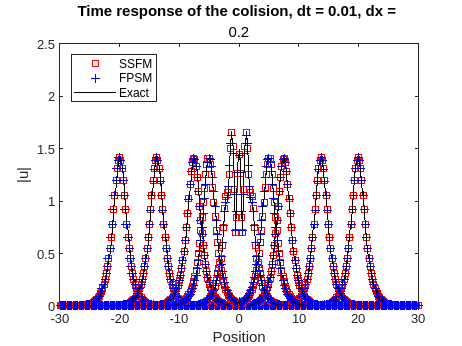

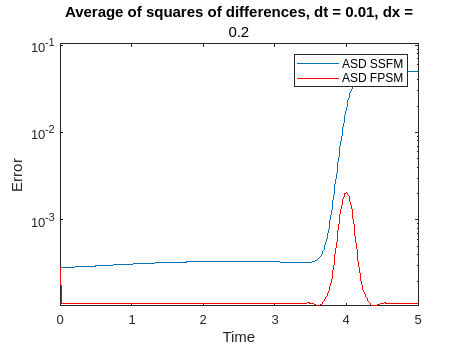

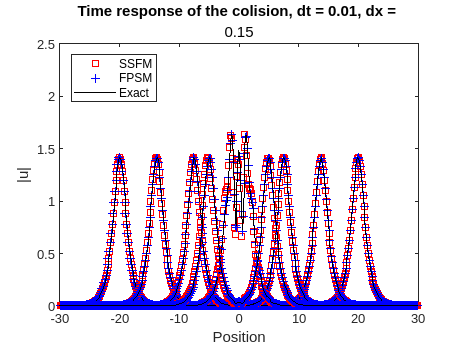

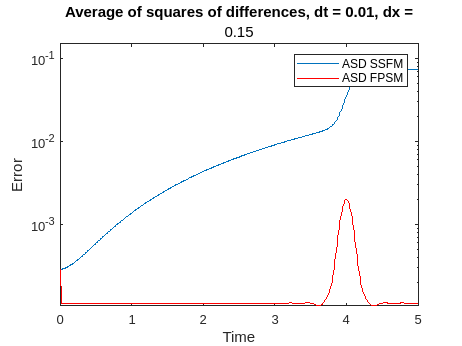

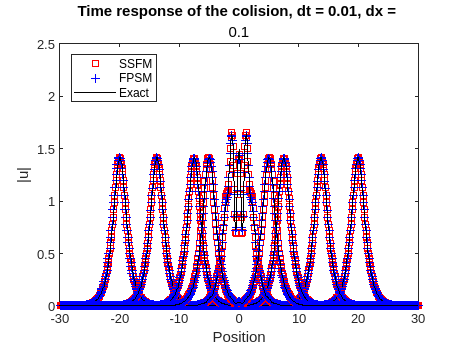

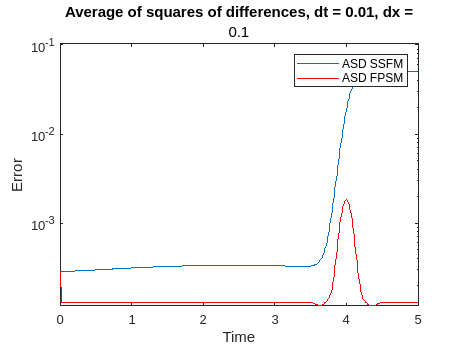

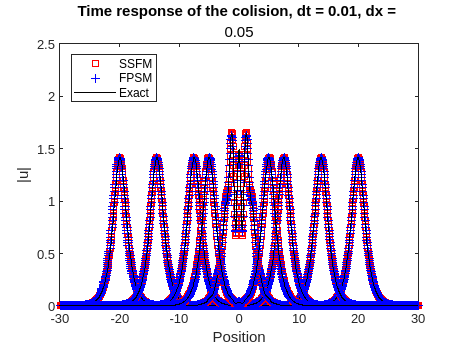

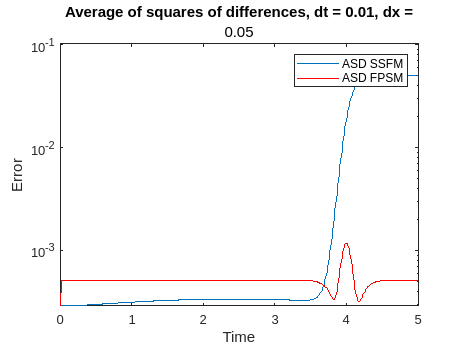

clear
clc
tf = 5;
dt = 0.01;
vdx = [0.2 0.15 0.1 0.05];
clf
LINF = zeros(length(vdx),2);

for w=1:length(vdx)
    dx = vdx(w);
    L = 100; % Intervalo de espacio
    N = L/dx; % Numero de intervalos en x
    
    n = (-N/2: 1 : N/2 - 1)';
    x = n * dx; % Espacio
    k = 2 * n * pi / L; % Wavenumbers
    
    
    M = tf/dt; 
    m = (1 : 1 : M)';
    t = m * dt;
    
    x0=-20; % Posicion inicial
    x1=20;
    psi=1;
    eta=1; % Amplitud
    v=5; % Velocidad
    v2=-5;
    
    
    f=@(x,t) (2*eta)^(0.5)*exp(1i*(0.5*v*x+(eta-0.25*v^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v*t-x0)) + (2*eta)^(0.5)*exp(1i*(0.5*v2*x+(eta-0.25*v2^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v2*t-x1));
    
    u1 = zeros(length(x),length(t)); % Split-step resultados
    u2 = zeros(length(x),length(t)); % Fourier pseudospectral resultados
    ut = zeros(length(x),length(t));

    u1(:,1)=f(x,0);             u2(:,1)=f(x,0);         
    u1(:,end)=f(x,t(end));      u2(:,end)=f(x,t(end)); 
    u1(1,:)=f(-L,t);            u2(1,:)=f(-L,t);       
    u1(end,:)=f(L,t);           u2(end,:)=f(L,t);      
    
    q=u1(:,1);
    
    ut(:,1) = f(x,t(1));
    for m = 2:length(t)
        %SSFM
        q = ifft(fftshift(fftshift(fft(exp(dt * 1i * (abs(q).*abs(q))) .* q)).*exp(-dt * 1i * k.*k)));
        u1(2:end-1,m) = q(2:end-1);
    
        %FPSM
        qn = f(x,t(m-1)) + 2*1i*ifft(sin(k.^2*(pi^2/L^2)*dt).*fft(f(x,t(m))))-4*1i*dt*(abs(f(x,t(m))) .* abs(f(x,t(m)))) .* f(x,t(m));
        u2(2:end-1,m) = qn(2:end-1);
    
        ut(:,m) = f(x,t(m));
    end
    figure;
    plot(x, abs(u1(:,1)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,1)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,1)),'k-',LineWidth=1);

    plot(x, abs(u1(:,end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end/4)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end/4)),'k-',LineWidth=1);
    
    plot(x, abs(u1(:,end/2)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end/2)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end/2)),'k-',LineWidth=1);

    plot(x, abs(u1(:,3*end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,3*end/4)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,3*end/4)),'k-',LineWidth=1);

    plot(x, abs(u1(:,end)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end)),'k-',LineWidth=1);

    ylim([0,eta*(5/2)])
    xlim([-30,30])
    xlabel('Position');
    ylabel('|u|') 

    title('Time response of the colision, dt = 0.01, dx = ' , num2str(dx));
    legend('SSFM','FPSM','Exact','Location', 'northwest')
    hold off
    
    figure;
    error1=mean(abs((ut-u1).^2),1)'; error2=mean(abs((ut-u2).^2),1)';
    semilogy(t,error1)
    hold on
    semilogy(t,error2,'r')
    legend('ASD SSFM', 'ASD FPSM')
    xlabel('Time')
    ylabel('Error')
    ylim([0,max(error2)+2*max(error1)])
    title('Average of squares of differences, dt = 0.01, dx =' , num2str(dx));
    hold off
    Linf1=max(mean(abs(ut-u1)));
    Linf2=max(mean(abs(ut-u2)));
    LINF(w,:) = [Linf1, Linf2];
end


LINF

LINF =     0.0708    0.0056
    0.0759    0.0056
    0.0708    0.0056
    0.0708    0.0080


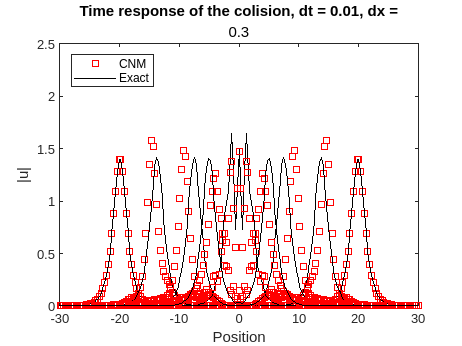

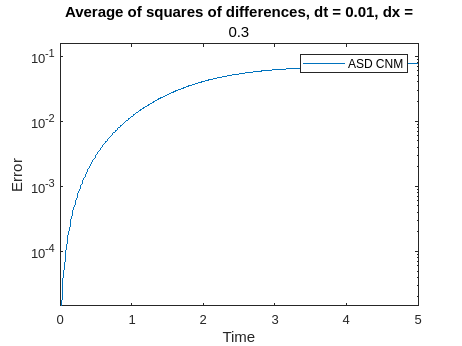

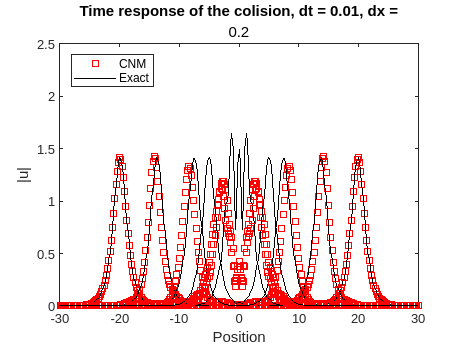

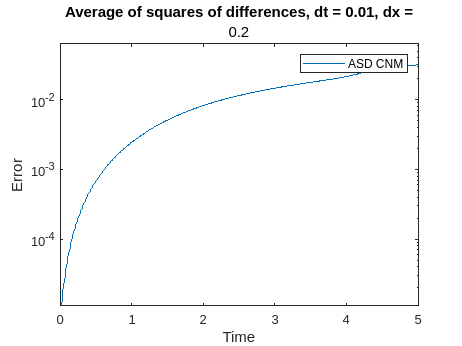

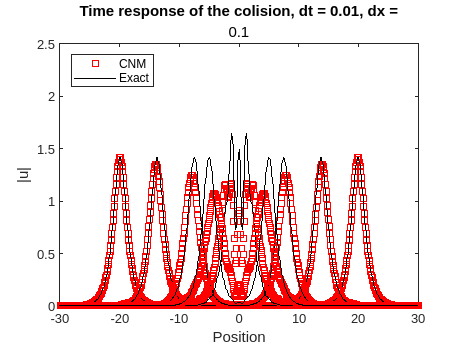

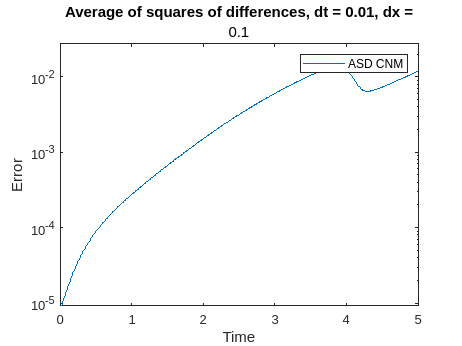

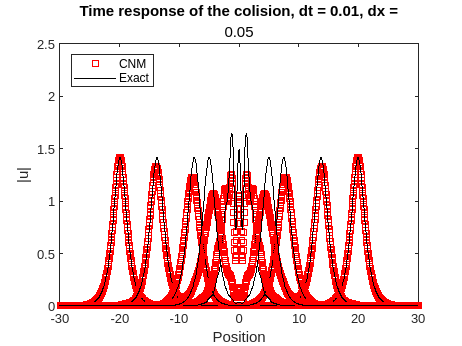

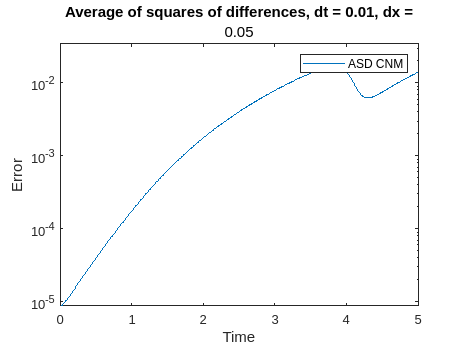

clear
clc
tf = 5;
dt = 0.01;
vdx = [0.3 0.2 0.1 0.05];
clf
LINF = zeros(length(vdx),1);
for w=1:length(vdx)
    dx = vdx(w);
    L = 100;
    N = floor(L/dx); 
    n = (-N-1 : 1 : N)';
    x = n * dx;

    M = floor(tf/dt);
    
    m = (1 : 1 : M)';
    t = m * dt;
    
    x0=-20; % Posicion inicial
    x1=20;
    psi=1;
    eta=1; % Amplitud
    v=5; % Velocidad
    v2=-5;
    
    
    q = @(x,t) (2*eta)^(0.5)*exp(1i*(0.5*v*x+(eta-0.25*v^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v*t-x0)) + (2*eta)^(0.5)*exp(1i*(0.5*v2*x+(eta-0.25*v2^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v2*t-x1));
    
    
    lambda=1/(2*(dx^2));
    
    u = zeros(2*N+2,M);
    ut = zeros(2*N+2, M);
    
    
    u(:,1) = q(x,t(1));
    ut(:,1) = q(x,t(1));
    
    
    A = zeros(2*N+2,2*N+2);
    B = zeros(2*N+2,2*N+2);
    
    
    for i=1:2*N+2
        A(i,i) = (1i/dt - 1/(dx^2));
        B(i,i) = (1i/dt + 1/(dx^2));
        if i>1
            A(i-1,i)= lambda; A(i,i-1)=  lambda;
            B(i-1,i)= -lambda; B(i,i-1)=  -lambda;
        end
    end
    F = -(abs(u(:,1)).^2).*u(:,1)+B*u(:,1)-(abs(u(:,1)).^2).*u(:,1);
    u(:,2) = A\F;
    ut(:,2) = q(x,t(2));
    
    
    for j=2:M-1
        F = -(abs(u(:,j+1)).^2).*u(:,j+1)+B*u(:,j)-(abs(u(:,j)).^2).*u(:,j);
        u(:,j+1)= A\F;
        ut(:,j+1) = q(x,t(j+1));
    end
    figure;
    plot(x, abs(u(:,1)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,1)),'k-',LineWidth=1);

    plot(x, abs(u(:,end/4)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,end/4)),'k-',LineWidth=1);
    
    plot(x, abs(u(:,end/2)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(ut(:,end/2)),'k-',LineWidth=1);

    plot(x, abs(u(:,3*end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(ut(:,3*end/4)),'k-',LineWidth=1);

    plot(x, abs(u(:,end)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,end)),'k-',LineWidth=1);

    ylim([0,eta*(5/2)])
    xlim([-30,30])
    xlabel('Position');
    ylabel('|u|') 
    
    title('Time response of the colision, dt = 0.01, dx =' ,num2str(dx));
    legend('CNM','Exact','Location', 'northwest')
    hold off
    figure;
    error1=mean(abs((ut-u).^2),1)';
    semilogy(t,error1)
    legend('ASD CNM')
    xlabel('Time')
    ylabel('Error')
    ylim([0,2*max(error1)])
    title('Average of squares of differences, dt = 0.01, dx =' , num2str(dx));
    hold off
    Linf1=max(mean(abs(ut-u)));
    LINF(w,1) = Linf1;
end


LINF

LINF =     0.0760
    0.0488
    0.0281
    0.0304


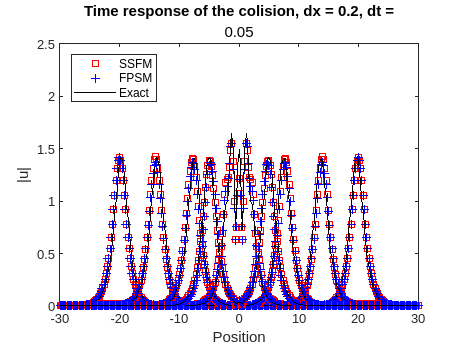

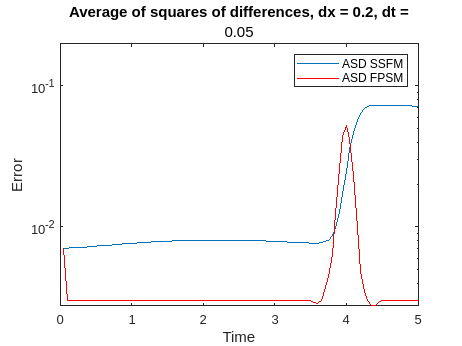

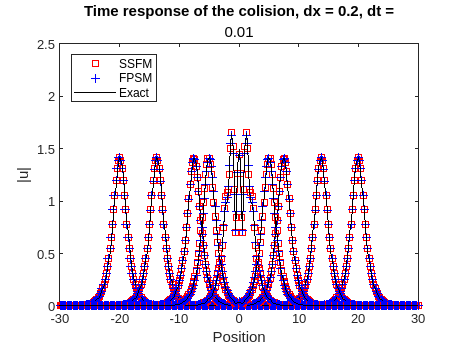

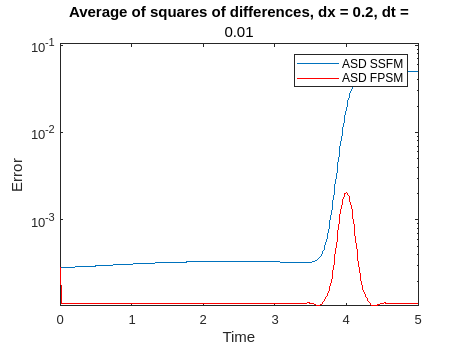

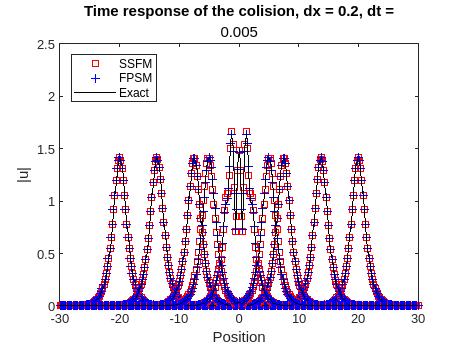

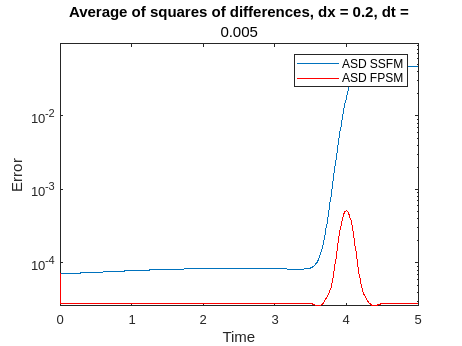

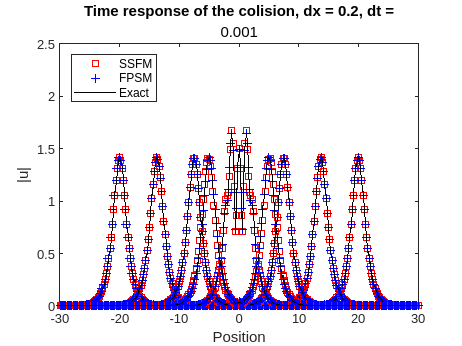

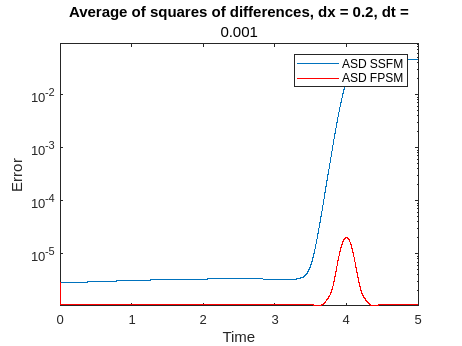

clear
clc
tf = 5;
dx = 0.2;
vdt = [0.05 0.01 0.005 0.001];
clf
LINF = zeros(length(vdt),2);

for w=1:length(vdt)
    L = 100; % Intervalo de espacio
    N = L/dx; % Numero de intervalos en x
    
    n = (-N/2: 1 : N/2 - 1)';
    x = n * dx; % Espacio
    k = 2 * n * pi / L; % Wavenumbers
    
    dt= vdt(w);
    M = tf/dt; 
    m = (1 : 1 : M)';
    t = m * dt;
    
    x0=-20; % Posicion inicial
    x1=20;
    psi=1;
    eta=1; % Amplitud
    v=5; % Velocidad
    v2=-5;
    
    
    f=@(x,t) (2*eta)^(0.5)*exp(1i*(0.5*v*x+(eta-0.25*v^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v*t-x0)) + (2*eta)^(0.5)*exp(1i*(0.5*v2*x+(eta-0.25*v2^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v2*t-x1));
    
    u1 = zeros(length(x),length(t)); % Split-step resultados
    u2 = zeros(length(x),length(t)); % Fourier pseudospectral resultados
    ut = zeros(length(x),length(t));
    
    
    
    u1(:,1)=f(x,0);             u2(:,1)=f(x,0);         
    u1(:,end)=f(x,t(end));      u2(:,end)=f(x,t(end)); 
    u1(1,:)=f(-L,t);            u2(1,:)=f(-L,t);       
    u1(end,:)=f(L,t);           u2(end,:)=f(L,t);      
    
    q=u1(:,1);
    
    ut(:,1) = f(x,t(1));
    for m = 2:length(t)
        %SSFM
        q = ifft(fftshift(fftshift(fft(exp(dt * 1i * (abs(q).*abs(q))) .* q)).*exp(-dt * 1i * k.*k)));
        u1(2:end-1,m) = q(2:end-1);
    
        %FPSM
        qn = f(x,t(m-1)) + 2*1i*ifft(sin(k.^2*(pi^2/L^2)*dt).*fft(f(x,t(m))))-4*1i*dt*(abs(f(x,t(m))) .* abs(f(x,t(m)))) .* f(x,t(m));
        u2(2:end-1,m) = qn(2:end-1);
    
        ut(:,m) = f(x,t(m));
    end
    figure;
    plot(x, abs(u1(:,1)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,1)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,1)),'k-',LineWidth=1);

    plot(x, abs(u1(:,end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end/4)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end/4)),'k-',LineWidth=1);
    
    plot(x, abs(u1(:,end/2)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end/2)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end/2)),'k-',LineWidth=1);

    plot(x, abs(u1(:,3*end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,3*end/4)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,3*end/4)),'k-',LineWidth=1);

    plot(x, abs(u1(:,end)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(u2(:,end)),'b+',LineWidth=0.001);   
    hold  on
    plot(x, abs(ut(:,end)),'k-',LineWidth=1);

    ylim([0,eta*(5/2)])
    xlim([-30,30])
    xlabel('Position');
    ylabel('|u|') 

    title('Time response of the colision, dx = 0.2, dt =' , num2str(dt));
    legend('SSFM','FPSM','Exact','Location', 'northwest')
    hold off

    figure;
    error1=mean(abs((ut-u1).^2),1)'; error2=mean(abs((ut-u2).^2),1)';
    semilogy(t,error1)
    hold on
    semilogy(t,error2,'r')
    legend('ASD SSFM', 'ASD FPSM')
    xlabel('Time')
    ylabel('Error')
    ylim([0,max(error2)+2*max(error1)])
    title('Average of squares of differences, dx = 0.2, dt =' , num2str(dt));
    hold off
    Linf1=max(mean(abs(ut-u1)));
    Linf2=max(mean(abs(ut-u2)));
    LINF(w,:) = [Linf1, Linf2];
end


LINF

LINF =     0.0891    0.0281
    0.0708    0.0056
    0.0686    0.0028
    0.0668    0.0006


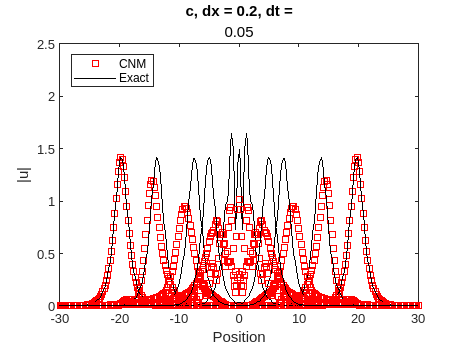

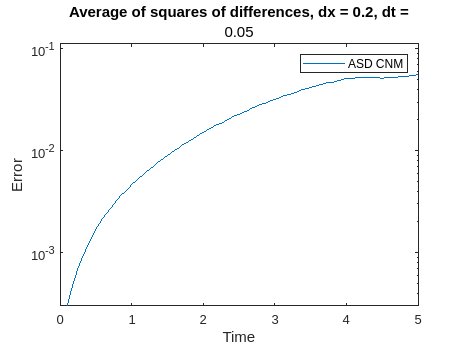

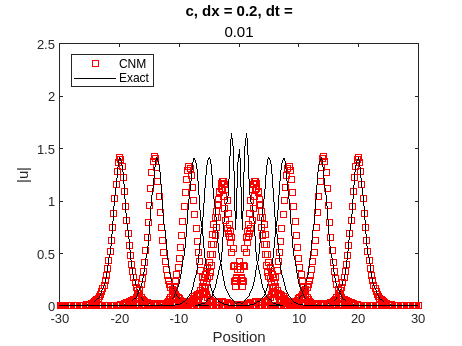

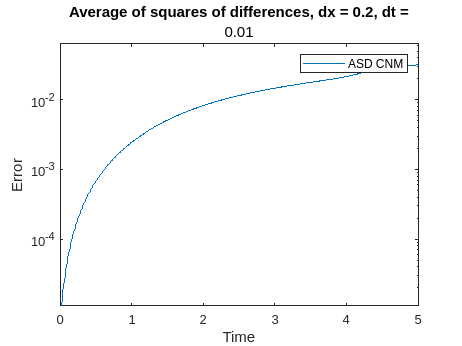

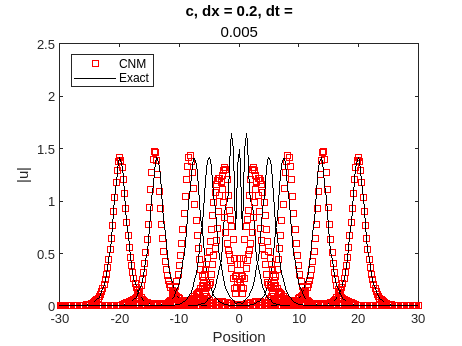

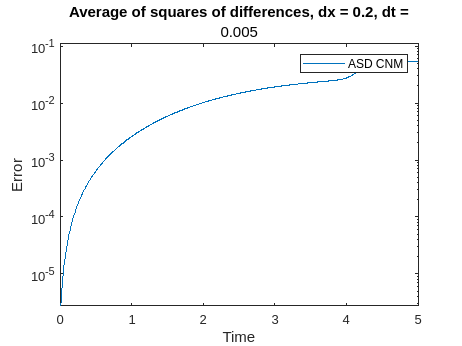

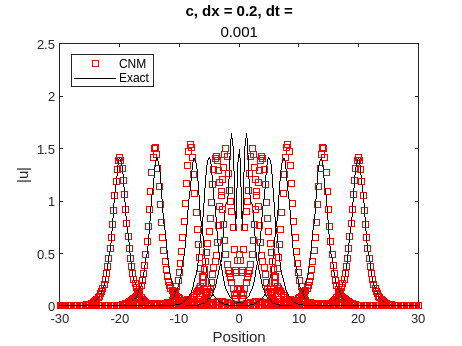

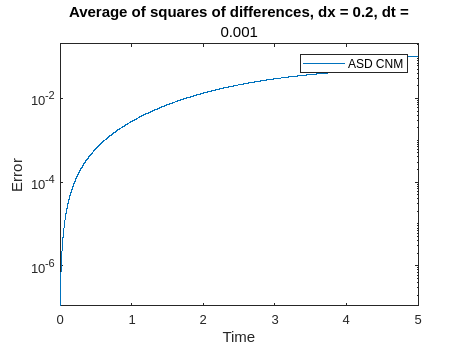

clear
clc
tf = 5;
dx = 0.2;
vdt = [0.05 0.01 0.005 0.001];
LINF = zeros(length(vdt),1);
clf
for w=1:length(vdt)
    L = 100;
    N = floor(L/dx); 
    n = (-N-1 : 1 : N)';
    x = n * dx;

    dt = vdt(w);
    M = floor(tf/dt);
    
    m = (1 : 1 : M)';
    t = m * dt;
    
    x0=-20; % Posicion inicial
    x1=20;
    psi=1;
    eta=1; % Amplitud
    v=5; % Velocidad
    v2=-5;
    
    
    q = @(x,t) (2*eta)^(0.5)*exp(1i*(0.5*v*x+(eta-0.25*v^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v*t-x0)) + (2*eta)^(0.5)*exp(1i*(0.5*v2*x+(eta-0.25*v2^2)*t+psi))...
                .*sech(eta^(0.5)*(x-v2*t-x1));
    
    lambda=1/(2*(dx^2));
    
    u = zeros(2*N+2,M);
    ut = zeros(2*N+2, M);
    
    
    u(:,1) = q(x,t(1));
    ut(:,1) = q(x,t(1));
    
    
    A = zeros(2*N+2,2*N+2);
    B = zeros(2*N+2,2*N+2);
    
    
    for i=1:2*N+2
        A(i,i) = (1i/dt - 1/(dx^2));
        B(i,i) = (1i/dt + 1/(dx^2));
        if i>1
            A(i-1,i)= lambda; A(i,i-1)=  lambda;
            B(i-1,i)= -lambda; B(i,i-1)=  -lambda;
        end
    end
    F = -(abs(u(:,1)).^2).*u(:,1)+B*u(:,1)-(abs(u(:,1)).^2).*u(:,1);
    u(:,2) = A\F;
    ut(:,2) = q(x,t(2));
    
    
    for j=2:M-1
        F = -(abs(u(:,j+1)).^2).*u(:,j+1)+B*u(:,j)-(abs(u(:,j)).^2).*u(:,j);
        u(:,j+1)= A\F;
        ut(:,j+1) = q(x,t(j+1));
    end
    figure;
    plot(x, abs(u(:,1)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,1)),'k-',LineWidth=1);

    plot(x, abs(u(:,end/4)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,end/4)),'k-',LineWidth=1);
    
    plot(x, abs(u(:,end/2)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(ut(:,end/2)),'k-',LineWidth=1);

    plot(x, abs(u(:,3*end/4)),'rs',LineWidth=0.001);
    hold on
    plot(x, abs(ut(:,3*end/4)),'k-',LineWidth=1);

    plot(x, abs(u(:,end)),'rs',LineWidth=0.001);
    hold  on
    plot(x, abs(ut(:,end)),'k-',LineWidth=1);

    ylim([0,eta*(5/2)])
    xlim([-30,30])
    xlabel('Position');
    ylabel('|u|') 

    title('c, dx = 0.2, dt =' , num2str(dt));
    legend('CNM','Exact','Location', 'northwest')
    hold off
    figure;
    error1=mean(abs((ut-u).^2),1)';
    semilogy(t,error1)
    legend('ASD CNM')
    xlabel('Time')
    ylabel('Error')
    ylim([0,2*max(error1)])
    title('Average of squares of differences, dx = 0.2, dt =' , num2str(dt));
    hold off
    Linf1=max(mean(abs(ut-u)));
    LINF(w,1) = Linf1;
end


LINF

LINF =     0.0644
    0.0488
    0.0610
    0.0769
